n = 30

n = 30


tic
fibonacci_recursive(n)

ans = 832040

fib_recursive = toc

fib_recursive = 0.1225


tic
fibonacci_tabulation(n)

ans = 832040

fib_tabulation1 = toc

fib_tabulation1 = 0.0159


tic
fibonacci_memoization(n)

ans = 832040

fib_memoization1 = toc

fib_memoization1 = 0.0079


tic
fibonacci_tabulation(n)

ans = 832040

fib_tabulation2 = toc

fib_tabulation2 = 0.0045


tic
fibonacci_memoization(n)

ans = 832040

fib_memoization2 = toc

fib_memoization2 = 0.0088

W = 100

W = 100

wt = [18 42 35 56 90 23 119 35]

wt =     18    42    35    56    90    23   119    35


Values = [140 89 29 46 73 67 100 50]

Values =    140    89    29    46    73    67   100    50


n = length(Values)

n = 8


tic
knapsack_recursive(W,wt,Values,n)

ans = 296

knap_recursive = toc

knap_recursive = 0.0156


tic
knapsack_memoization(W,wt,Values,n)

ans = 296

knap_memoization1 = toc

knap_memoization1 = 0.0203


tic
knapsack_tabulation(W,wt,Values,n)

ans = 296

knap_tabulation1 = toc

knap_tabulation1 = 0.0202


tic
knapsack_memoization(W,wt,Values,n)

ans = 296

knap_memoization2 = toc

knap_memoization2 = 0.0164


tic
knapsack_tabulation(W,wt,Values,n)

ans = 296

knap_tabulation2 = toc

knap_tabulation2 = 0.0107

# Tables of Results


Number = {'Fibonccis Problem'; 'Knapsack Problem'};
CompTime_recursive = [fib_recursive; knap_recursive];
CompTime_memoization = [(fib_memoization1+fib_memoization2)/2; (knap_memoization1+knap_memoization2)/2];
CompTime_tabulation = [(fib_tabulation1+fib_tabulation2)/2; (knap_tabulation1+knap_tabulation2)/2];

General_table = table(Number,CompTime_recursive,CompTime_memoization,CompTime_tabulation)

General_table = 2×4 table
           Number            CompTime_recursive    CompTime_memoization    CompTime_tabulation
    _____________________    __________________    ____________________    ___________________

    {'Fibonccis Problem'}          0.12247              0.0083753               0.010173      
    {'Knapsack Problem' }         0.015594               0.018354               0.015461      


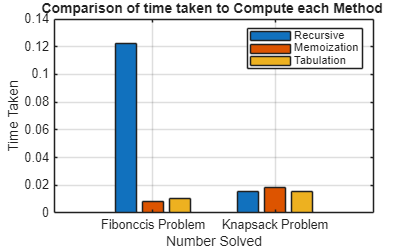


bar(Number,[General_table.CompTime_recursive,General_table.CompTime_memoization,General_table.CompTime_tabulation])
grid on
legend(["Recursive", "Memoization", "Tabulation"]);
xlabel('Number Solved'); 
ylabel('Time Taken');
title('Comparison of time taken to Compute each Method ')